clc;
clear;
close all;

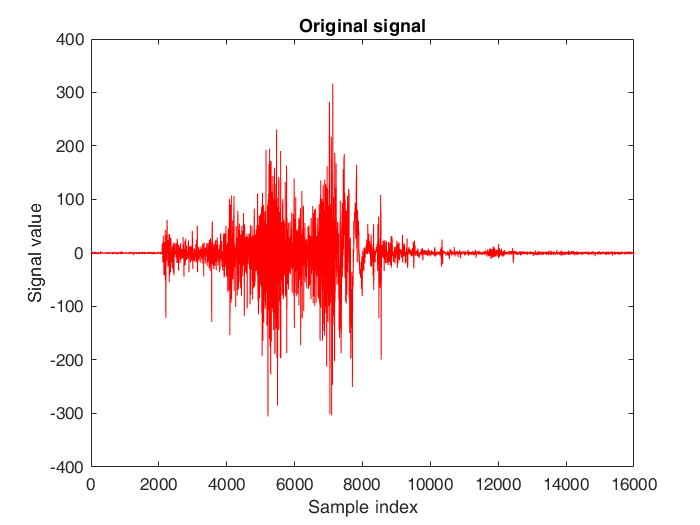

d = load("subject_01.mat");
cell_array = d.act_01_ch_1;
signal = cell_array(:,1); % Change this line to create a single column vector
% cell_array = d{1};
plot(signal,'r');
xlabel('Sample index');
ylabel('Signal value');
title("Original signal");
hold on;

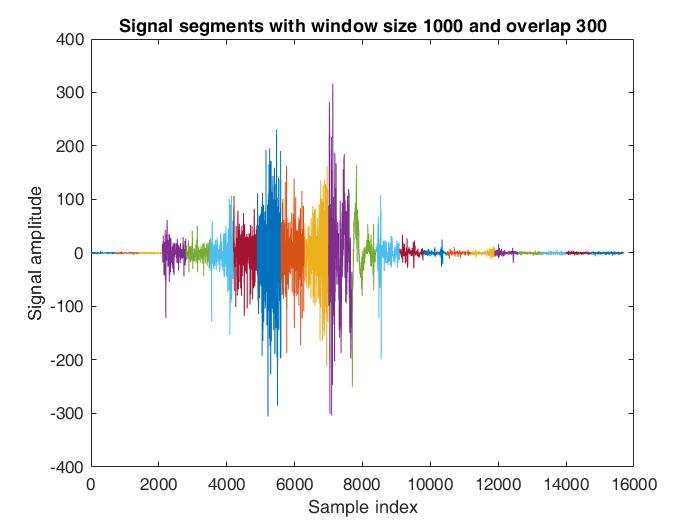

% Assume 'signal' is the signal that you want to segment and plot
window_size = 1000; % Define the window size
overlap = 300; % Define the overlap
num_segments = floor((length(signal) - window_size) / (window_size-overlap)) + 1; % Calculate the number of segments

figure; % Create a new figure to plot the segments

for i = 1:num_segments
    start_index = (i-1)*(window_size-overlap) + 1;
    end_index = start_index + window_size - 1;
    
    % Check if the end index is larger than the length of the signal
    if end_index > length(signal)
        end_index = length(signal);
    end
    
    % Extract the segment from the signal
    segment = signal(start_index:end_index);
    
    % Plot the segment
    plot(start_index:end_index, segment);
    
    hold on; % Hold the plot for the next segment
end

xlabel('Sample index');
ylabel('Signal amplitude');
title('Signal segments with window size 1000 and overlap 300');

hold off;